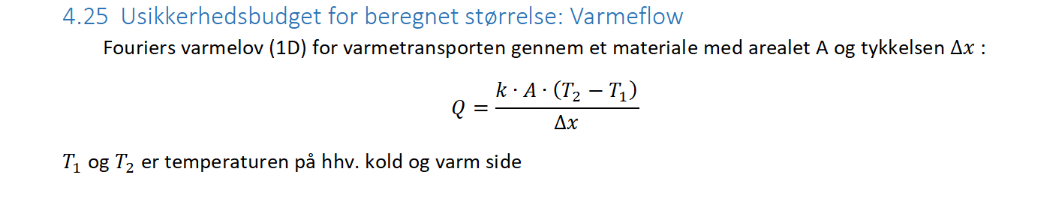

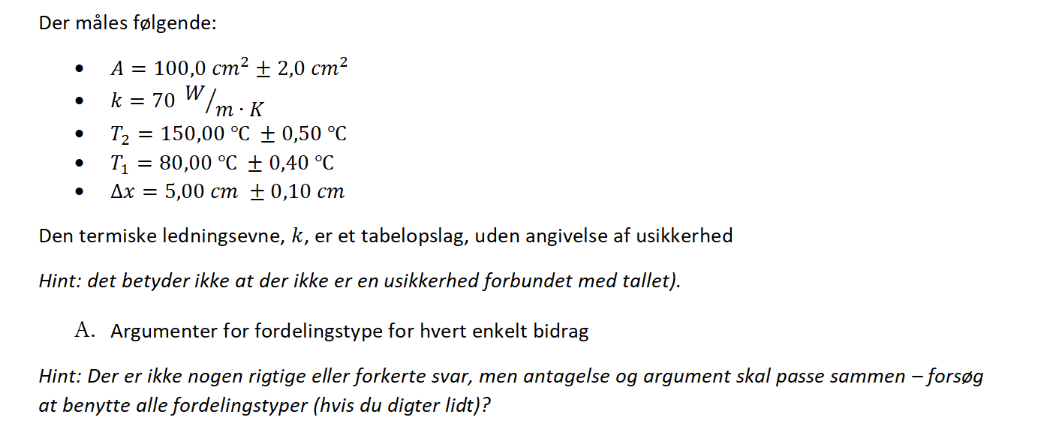

A kan anses som at være 2 terninger dat det er l * h så det kan argumenteres for at man får en trækant fordeling.

k er en opslags værdig så dens fordeling er højst sandsynlig en normal fordeling

De to temperature er nok firkant fordelinger da jeg kunne forstille mig at chancen er lige stor for de forskellige målinger

$\Delta x
$ kan måske forstilles at være en u fordeling vis man bruger en tommelstock til at måle f.eks. hvor man siger "close enough"

u = symunit; 
syms us a

firkant_fordeling = us == a/sqrt(3) ;  %opskrive forskellige formler for de forskellige fordelinger 
u_fordeling = us == a/sqrt(2) ; 
trekant_fordeling = us == a/sqrt(6) ;
format longG
A_alpha = 2/100/100

A_alpha =                     0.0002


k_alpha = 0.5 ; %Antager ussikerhed 
T2_alpha = 0.5;
T1_alpha = 0.4;
delta_X_alpha = 0.1/100

delta_X_alpha =                      0.001


u_A = vpa(solve(subs(trekant_fordeling,a,A_alpha), us), 4) %substituere værdiger ind i fordelings udregningerne

$$u\_A = 8.165e-5$$

u_T2 = vpa(solve(subs(firkant_fordeling,a,T2_alpha), us), 4)

$$u\_T2 = 0.2887$$

u_T1 = vpa(solve(subs(firkant_fordeling,a,T1_alpha), us), 4)

$$u\_T1 = 0.2309$$

u_delta_x = vpa(solve(subs(u_fordeling,a,delta_X_alpha), us), 4)

$$u\_delta\_x = 0.0007071$$

u_k = vpa(solve(subs(trekant_fordeling,a,k_alpha), us), 4) %nok en normal fordeling men vi approksimere med en trekants fordeling

$$u\_k = 0.2041$$

%% der laves ikke over k da ussikerheden er antaget.


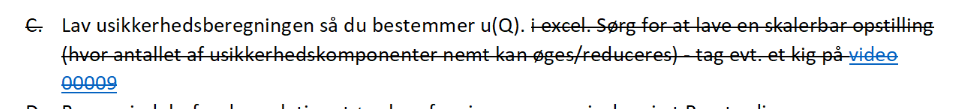

syms A T2 T1 delta_x k
Q = (k * A * (T2 - T1)) / delta_x;
vars = symvar(Q)

$$vars = \left(\begin{array}{ccccc} A & T_{1} & T_{2} & \delta_{x} & k \end{array}\right)$$

var_vals =[100/100/100 80 150 5/100 70];
var_ussikerheder = [u_A u_T1 u_T2 u_delta_x u_k];
STAT.Ophobningsloven(Q, vars, var_vals, var_ussikerheder) %% Svaret skulle gerne være i watt 

$$ds = \left(\begin{array}{ccccc} -\frac{k\,\left(T_{1}-T_{2}\right)}{\delta_{x}} & -\frac{A\,k}{\delta_{x}} & \frac{A\,k}{\delta_{x}} & \frac{A\,k\,\left(T_{1}-T_{2}\right)}{{\delta_{x}}^{2}} & -\frac{A\,\left(T_{1}-T_{2}\right)}{\delta_{x}} \end{array}\right)$$

$$ans = 17.060480649741019575455093762421$$

Kode til ophobnings funktionen 